# **Training CN-vs-MCIc**

Due to memory (RAM) and computational power limits, instead of converting each MRI in 100 pictures, in this code we are going to extract only 6 slices for each MRI, train on 3 folds instead of 20, and not perform any data augmentation.

### **Code structure:**

**1) Define the network (Transfer Learning from AlexNet)**

**2) Set training parameters**

**3) Load the Dataset:**

- Load .mat files

- Concatenate CN_training, CN_testing, etc... in a single cell array

- Transform the 238 MRI images into 714 (=238*3) 227x227x3 images (~1GB)

**4) Cross Fold Validation (for 2 folds):**

- Find patterns to use for Testing (index==fold) and Training (index!=fold) and split the dataset in Training and Testing for this fold

- Shuffle the trainingImages (and their labels, respectively)

- Train

- Save the trained model

- Validate on TestSet

- Compute Metrics

## **Problem parameters**

clear all
warning off

% Type of problem
%problem="CN_vs_MCIc";
problem="CN_vs_AD";
%problem="MCInc_vs_MCIc";

% Axis
axis="x-axis"
%axis="y-axis"
%axis="z-axis"

axis = "z-axis"


nPictures=6; % Number of pictures to extract form each MRI
gap=2; % Number of slices between pictures
k=1; %

totSlicesInvolved = (2*k + 1 + gap)*nPictures - gap; %max 100


%---------------------------------------------------------------
time=datestr(now,"yyyy_mm_dd_HH_MM"); %Save execution time

% where to save current execution outputs
directory="../TrainedModels/"+problem+"/"+axis+"/"+time+"/";
% Create directories if doesn't exist
if ~exist("../TrainedModels", 'dir')
   mkdir("../TrainedModels")
end
if ~exist("../TrainedModels/"+problem, 'dir')
   mkdir("../TrainedModels/"+problem)
end
if ~exist("../TrainedModels/"+problem+"/"+axis, 'dir')
   mkdir("../TrainedModels/"+problem+"/"+axis)
end
mkdir("../TrainedModels/"+problem+"/"+axis+"/"+time)

## **1) Define the Network**

by modifing the last 3 layers of AlexNet

siz=[227 227]; % input size of the CNN (AlexNet)

net = alexnet;
layers=net.Layers;
layers(end-2)=fullyConnectedLayer(2,'WeightLearnRateFactor',20,'BiasLearnRateFactor',20);
layers(end-1)=softmaxLayer;
layers(end)=classificationLayer;

## **2) Set training parameters**

folds=3;

miniBatchSize = 24;
learningRate = 1e-4;
maxEpochs=20;
optimizer='sgdm';

options=trainingOptions(optimizer,...
    "MiniBatchSize",miniBatchSize,...
    "InitialLearnRate",learningRate,...
    'MaxEpochs',maxEpochs,...
    "L2Regularization",1e-04,...
    "Momentum", 0.889,...
    "Verbose",false,...
    'Shuffle','every-epoch',...
    "Plots","training-progress");

## **3) Load the Dataset**

**Load CN.mat and MCIc.mat**

**Concatenate CN_training, CN_testing, MCIc_training, MCIc_testing in a single cell array**

% Concatenate all dataset files in a single cell array
load("../../Dataset/CN.mat")
load("../../Dataset/AD.mat")
dataset=cat(1,CN_training,CN_testing,MCIc_training,MCIc_testing);

% Create label array
lengthClass1=(length(CN_training)+length(CN_testing));
lengthClass2=(length(MCIc_training)+length(MCIc_testing));
mriLabel(1:lengthClass1)=1; %Cognitive Normal = 1
mriLabel(lengthClass1:lengthClass1+lengthClass2)=2;

clear CN_training CN_testing MCIc_training MCIc_testing lengthClass1 lengthClass2

**Transform the 238 MRI images into 1428 (=238*6) 227x227x3 images (~1GB)**

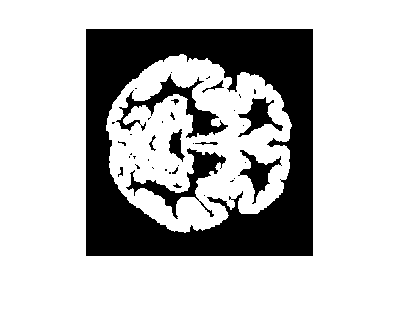

Images=[];
label=[]; % labels of classes 
labelID=[]; % labels of ID
tmpTR=1;
for i=1:length(mriLabel)
    % Extract single MRI
    IMG=dataset{i};

    % Transform MRI picture into nPictures images 227x227x3
    IMG=mriToCNN(IMG,siz,axis,nPictures,gap,k);
    Images(:,:,:,tmpTR:tmpTR+size(IMG,4)-1)=IMG;

    % Return label vector with labels of the new 3 pictures
    class=mriLabel(i);
    label(tmpTR:tmpTR+size(IMG,4)-1)=class;

    % Save single person's ID
    labelID(tmpTR:tmpTR+size(IMG,4)-1)=i;

    tmpTR=tmpTR+size(IMG,4); %Increasing counter by 3

    clear IMG;
end

clear dataset mriLabel class tmpTR

% Display sample of 1 picture
a(:,:,1)=Images(:,:,1,1);
a(:,:,2)=Images(:,:,2,1);
a(:,:,3)=Images(:,:,3,1);
imshow(a(:,:,1))

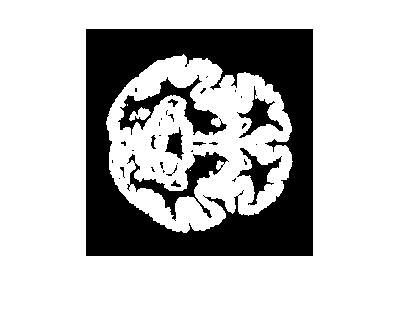

imshow(a(:,:,2))

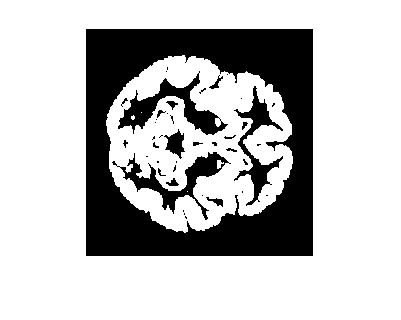

imshow(a(:,:,3))

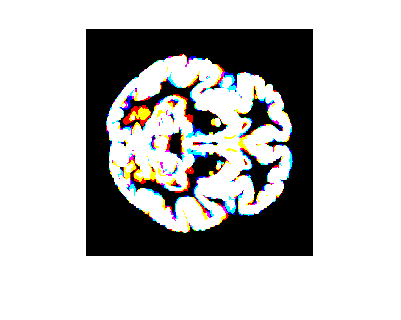

imshow(a)%Whole RGB picture

## **4) Cross fold validation (3 fold)**

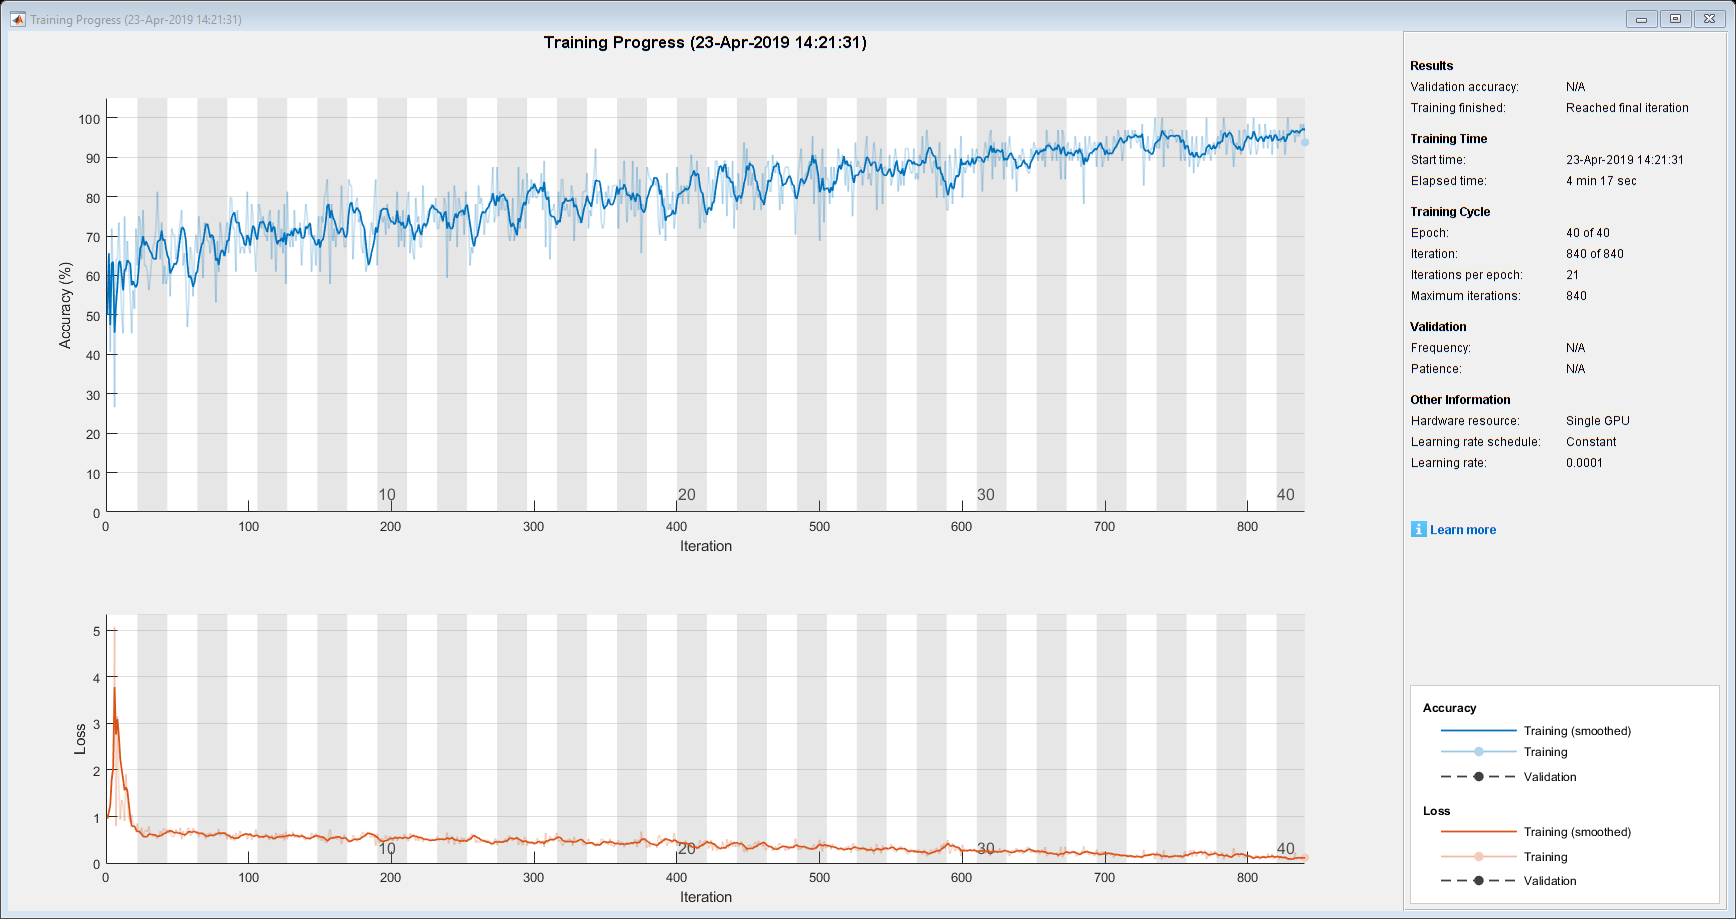

TP = 5

TN = 43

FP = 5

FN = 13

precision = 0.5000

recall = 0.2778

f1 = 0.3571

specificity = 0.1042

accuracy = 0.7273

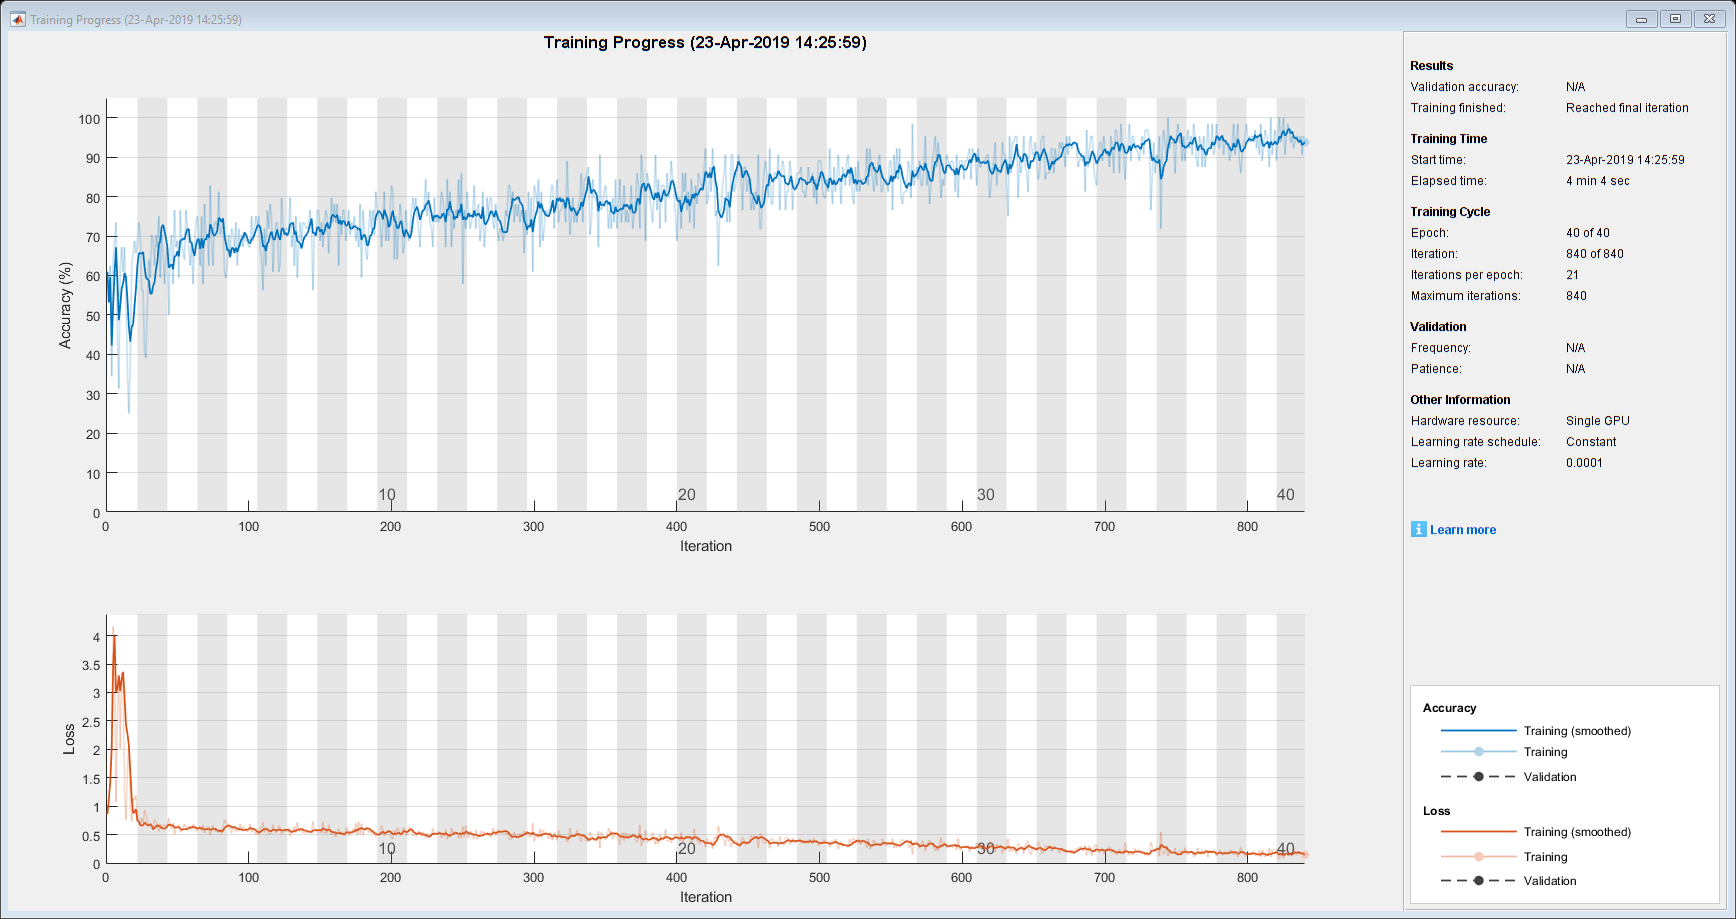

TP =      5    15


TN =     43    39


FP =      5     9


FN =     13     9


precision =     0.5000    0.6250


recall =     0.2778    0.6250


f1 =     0.3571    0.6250


specificity =     0.1042    0.1875


accuracy =     0.7273    0.7500


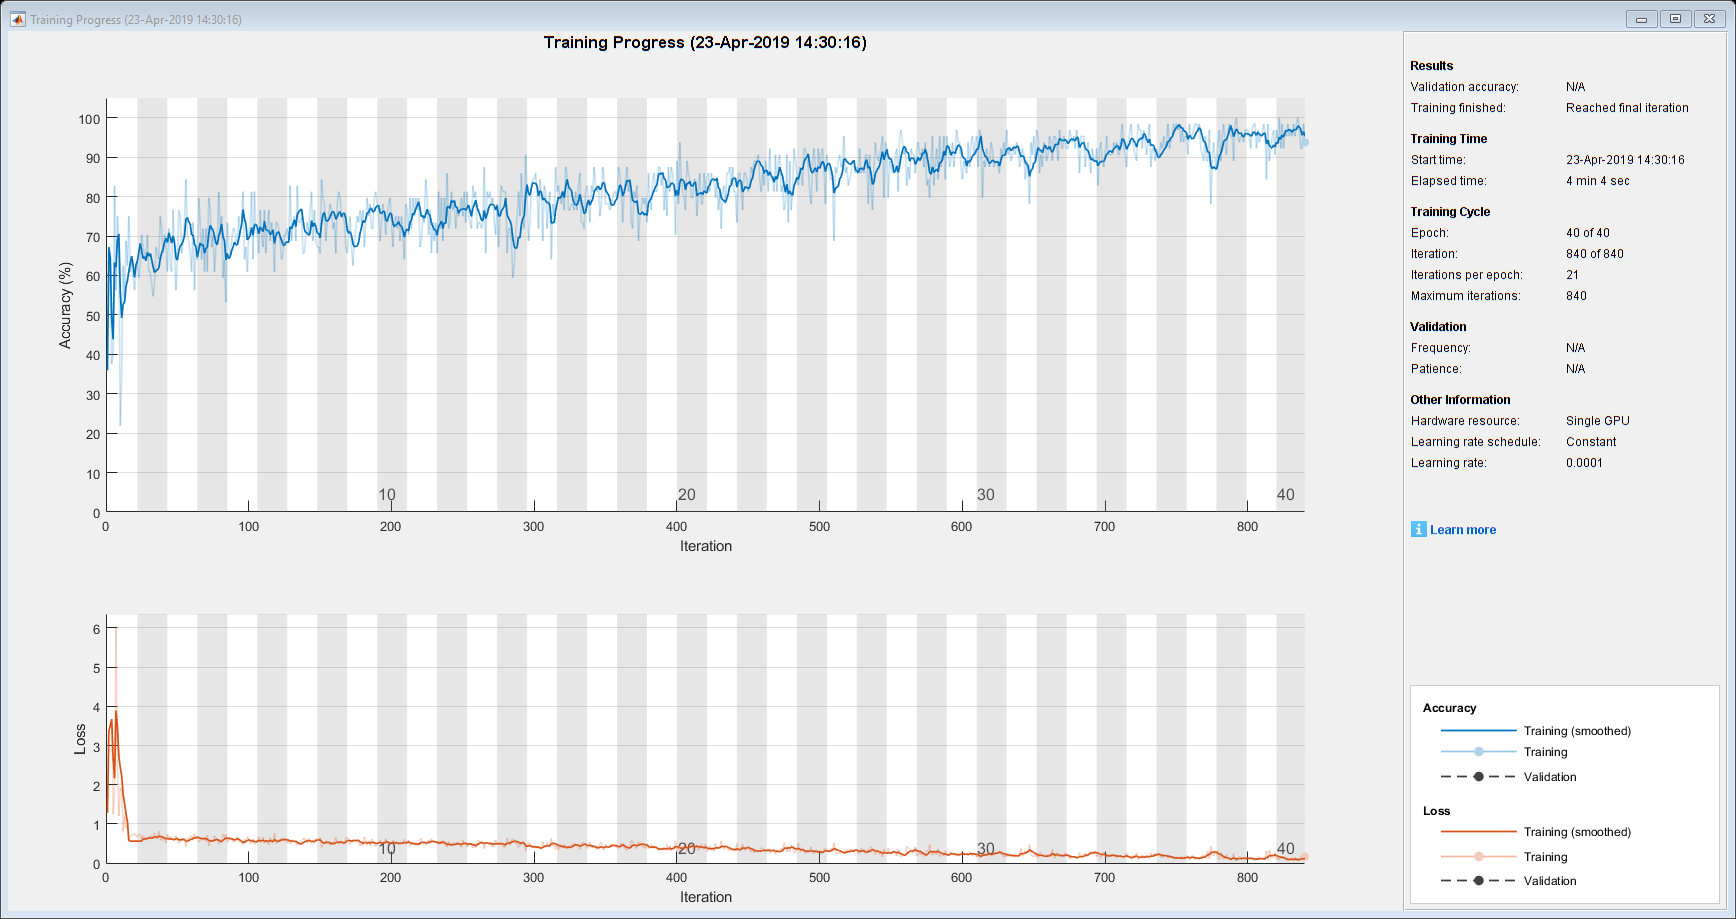

TP =      5    15     5


TN =     43    39    36


FP =      5     9    12


FN =     13     9    19


precision =     0.5000    0.6250    0.2941


recall =     0.2778    0.6250    0.2083


f1 =     0.3571    0.6250    0.2439


specificity =     0.1042    0.1875    0.2500


accuracy =     0.7273    0.7500    0.5694


for fold=1:folds

**            Find patterns to use for Testing (index==fold) and Training (index!=fold)**

    % Split the dataset in Training and Testing for this fold    
    load("../../Dataset/indices_CN-vs-AD.mat")
    
    trainingIndices=double([Indices~=fold])';
    trainingIndices=trainingIndices.*[1:length(trainingIndices)];
    trainingIndices=trainingIndices(trainingIndices~=0);

AvarageAccuracy = 0.6822

    trainingIndices=double(ismember(labelID,trainingIndices));
    trainingIndices=trainingIndices.*[1:length(trainingIndices)];
    trainingIndices=trainingIndices(trainingIndices~=0);
    
    trainingImages=Images(:,:,:,trainingIndices);
    trainingLabel=label(:,trainingIndices);
    trainingID=labelID(:,trainingIndices);
    
    testingIndices=double([Indices==fold])';
    testingIndices=testingIndices.*[1:length(testingIndices)];
    testingIndices=testingIndices(testingIndices~=0);
    testingIndices=ismember(labelID,testingIndices);
    testingIndices=testingIndices.*[1:length(testingIndices)];
    testingIndices=testingIndices(testingIndices~=0);
    
    testImages=Images(:,:,:,testingIndices);
    testLabel=label(:,testingIndices);
    testID=labelID(:,testingIndices);
    
    clear indices_CN-vs-MCIc.mat trainingIndices testingIndices

   **         Shuffle the trainingImages (and their labels respectively)**

    indicesVector=[1:length(trainingLabel)]; % indices from 1 to trainingImages length (~678)
    indicesVector=indicesVector(randperm(length(indicesVector))); % Shuffle vector of indices
    
    trainingImages=trainingImages(:,:,:,indicesVector);
    trainingLabel=trainingLabel(:,indicesVector);
    trainingID=trainingID(:,indicesVector);

            **Train**

    valueset = [1:2];
    Y=categorical(trainingLabel',valueset);
    
    [trainedNet,info]=trainNetwork(trainingImages,Y,layers,options);

**            Save the trained model**

    save(directory+"trainedModel"+fold+".mat", "trainedNet");
    save(directory+"trainingInfo"+fold+".mat","info");

            **Validation**

    [predictions, scores{fold}] = classify(trainedNet,testImages);

**            Metrics**

    predictions=double(predictions);

    TP(fold)= sum(and((predictions==2)',testLabel==2))
    TN(fold)= sum(and((predictions==1)',testLabel==1))
    FP(fold)= sum(and((predictions==2)',testLabel==1))
    FN(fold)= sum(and((predictions==1)',testLabel==2))
    
    precision(fold)= TP(fold)/(TP(fold)+FP(fold))
    recall(fold)=TP(fold)/(TP(fold)+FN(fold))
    f1(fold)=2*(precision(fold)*recall(fold))/(precision(fold)+recall(fold))
    specificity(fold)=FP(fold)/(FP(fold)+TN(fold))
    accuracy(fold)=(TP(fold)+TN(fold))/(TP(fold)+TN(fold)+FP(fold)+FN(fold))

    %confusionchart(testLabel,predictions)
    
    
    
end %end of cross fold validation

### **Save metrics and scores**

save(directory+"Metrics.mat","TP","TN","FP","FN","precision","recall","f1","specificity","accuracy")

save(directory+"Scores.mat","scores");

AvarageAccuracy=sum(accuracy)/3

function [IMG]=mriToCNN(IMG,siz,axis,nPictures,gap,k) 

    % Eg. with k=2, gap=2, nPictures=2
    % |x-k|___| x |___|x+k|___|___|x-k|___| x |___|x+k|
    %       k       k        gap        k       k
    
    % A picture is made of 3 slices
    % nPictures: Number of pictures to extract for each MRI
    % gap: number of slices between pictures 
    % k: .......
    %    k=0 means that all 3 channels of the picture are the same slice
    %    k=1 means that we pick 3 consecutive slices
    %    k=2 means that there is 1 slice between the 3 slices
    

    % Removing NaN values
    IMG(find(isnan(IMG)))=0;
    mriSize=size(IMG);
    
    % Extract 6 slices in sequence from the middle
    % Resize each 121x145 slice to 227x227
    for l=0:nPictures-1
        if axis=="x-axis"
            middle=floor(mriSize(1)/2); %index of the middle slice
            slice=middle-floor(((2*k+1+gap)*nPictures-gap)/2)+l*(gap+2*k+1); %index of the 1st slice of the picture
            I1=imresize(squeeze(IMG(slice,:,:)),[siz(1) siz(2)]);
            slice=middle-floor(((2*k+1+gap)*nPictures-gap)/2)+l*(gap+2*k+1)+k; %index of the 1st slice of the picture
            I2=imresize(squeeze(IMG(slice,:,:)),[siz(1) siz(2)]);
            slice=middle-floor(((2*k+1+gap)*nPictures-gap)/2)+l*(gap+2*k+1)+2*k; %index of the 1st slice of the picture
            I3=imresize(squeeze(IMG(slice,:,:)),[siz(1) siz(2)]);
        end
        if axis=="y-axis"
            middle=floor(mriSize(2)/2); %index of the middle slice
            slice=middle-floor(((2*k+1+gap)*nPictures-gap)/2)+l*(gap+2*k+1); %index of the 1st slice of the picture
            I1=imresize(squeeze(IMG(:,slice,:)),[siz(1) siz(2)]);
            slice=middle-floor(((2*k+1+gap)*nPictures-gap)/2)+l*(gap+2*k+1)+k; %index of the 1st slice of the picture
            I2=imresize(squeeze(IMG(:,slice,:)),[siz(1) siz(2)]);
            slice=middle-floor(((2*k+1+gap)*nPictures-gap)/2)+l*(gap+2*k+1)+2*k; %index of the 1st slice of the picture
            I3=imresize(squeeze(IMG(:,slice,:)),[siz(1) siz(2)]);
        end
        if axis=="z-axis"
            middle=floor(mriSize(3)/2); %index of the middle slice
            slice=middle-floor(((2*k+1+gap)*nPictures-gap)/2)+l*(gap+2*k+1); %index of the 1st slice of the picture
            I1=imresize(squeeze(IMG(:,:,slice)),[siz(1) siz(2)]);
            slice=middle-floor(((2*k+1+gap)*nPictures-gap)/2)+l*(gap+2*k+1)+k;%index of the 2nd slice of the picture
            I2=imresize(squeeze(IMG(:,:,slice)),[siz(1) siz(2)]);
            slice=middle-floor(((2*k+1+gap)*nPictures-gap)/2)+l*(gap+2*k+1)+2*k;%index of the 3rd slice of the picture
            I3=imresize(squeeze(IMG(:,:,slice)),[siz(1) siz(2)]);
        end
        RID(:,:,1,l+1)=I1;
        RID(:,:,2,l+1)=I2;
        RID(:,:,3,l+1)=I3;
        clear I1 I2 I3;
    end
    
    clear IMG
    
    % Normalize values
    M=max(RID(:));
    IMG=floor(RID.*(255/M));
    %IMG=floor(RID.*(1/M));
    
    clear RID
end